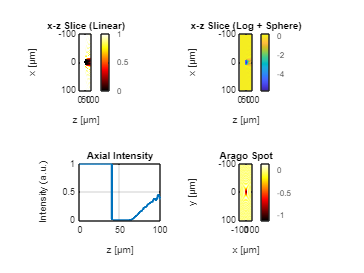

%% Parameters
lambda = 4e-6;          % Wavelength [m] (4 μm)
r0 = 10e-6;             % Sphere radius [m] (10 μm)
Nx = 256; Ny = 256; Nz = 512; 
zMax = 10 * r0;         % Propagation distance [m] (100 μm)
gridExtent = 20 * r0;   % Transverse grid extent [m] (±100 μm)

% Grid coordinates (symmetric around 0)
x = linspace(-gridExtent/2, gridExtent/2, Nx);
y = linspace(-gridExtent/2, gridExtent/2, Ny);
z = linspace(0, zMax, Nz);
dx = x(2) - x(1);       % Grid spacing (Δx ≈ 0.78125 μm)
dy = y(2) - y(1); 
dz = z(2) - z(1);       % Step size (Δz ≈ 0.1953 μm)

%% Create 3D refractive index profile (sphere)
[X3, Y3, Z3] = meshgrid(x, y, z);
sphereCenter = [0, 0, zMax/2]; % Sphere centered at z=50 μm
R = sqrt((X3 - sphereCenter(1)).^2 + (Y3 - sphereCenter(2)).^2 + (Z3 - sphereCenter(3)).^2);
n = ones(size(R)) + 1i*1e3; % Background: n = 1 + 1000i (opaque)
n(R > r0) = 1; % Sphere: n = 1 (transparent)

%% Input wave (2D plane at z=0)
E_input = ones(Nx, Ny); % Uniform amplitude '1'

%% Wave propagation (angular spectrum method)
k0 = 2*pi/lambda;
E = E_input;

% Spatial frequency grids (corrected)
fx = (-Nx/2:Nx/2-1)/(Nx*dx);
fy = (-Ny/2:Ny/2-1)/(Ny*dy);
[Fx, Fy] = meshgrid(fx, fy);

% Preallocate data
xZ_slice = zeros(Nx, Nz);
I_axial = zeros(1, Nz);

for iz = 1:Nz
    % Step 1: Apply absorption
    absorption = exp(-k0 * imag(n(:,:,iz)) * dz);
    E = E .* absorption;
    
    % Step 2: Propagate
    E_fft = fftshift(fft2(E));
    H = exp(1i*k0*dz*sqrt(1 - (lambda*Fx).^2 - (lambda*Fy).^2));
    E = ifft2(ifftshift(E_fft .* H));
    
    % Store data
    [~, y0] = min(abs(y));
    xZ_slice(:, iz) = abs(E(:, y0)).^2;
    [~, x0] = min(abs(x));
    I_axial(iz) = abs(E(x0, y0)).^2;
end

%% Visualization (Four Plots)
figure;

% Plot 1: x-z Slice (Linear Scale)
subplot(2,2,1);
imagesc(z*1e6, x*1e6, xZ_slice);
title('x-z Slice (Linear)'); xlabel('z [μm]'); ylabel('x [μm]');
colormap(gca, 'hot'); caxis([0 1]); colorbar;

% Plot 2: x-z Slice (Log Scale + Sphere Mask)
subplot(2,2,2);
sphere_mask = squeeze(real(n(:, Ny/2, :)) > 1);
xZ_log = log10(xZ_slice + 1e-6);
xZ_log(sphere_mask) = NaN; % Hide sphere region
imagesc(z*1e6, x*1e6, xZ_log);
title('x-z Slice (Log + Sphere)'); xlabel('z [μm]'); ylabel('x [μm]');
colormap(gca, 'parula'); colorbar;

% Plot 3: Axial Intensity
subplot(2,2,3);
plot(z*1e6, I_axial, 'LineWidth', 2);
title('Axial Intensity'); xlabel('z [μm]'); ylabel('Intensity (a.u.)');
xlim([0 100]); grid on;

% Plot 4: Fresnel Pattern (Arago Spot)
subplot(2,2,4);
output_plane = log10(abs(E).^2 + 1e-6);
imagesc(x*1e6, y*1e6, output_plane);
title('Arago Spot'); xlabel('x [μm]'); ylabel('y [μm]');
colormap(gca, 'hot'); colorbar;